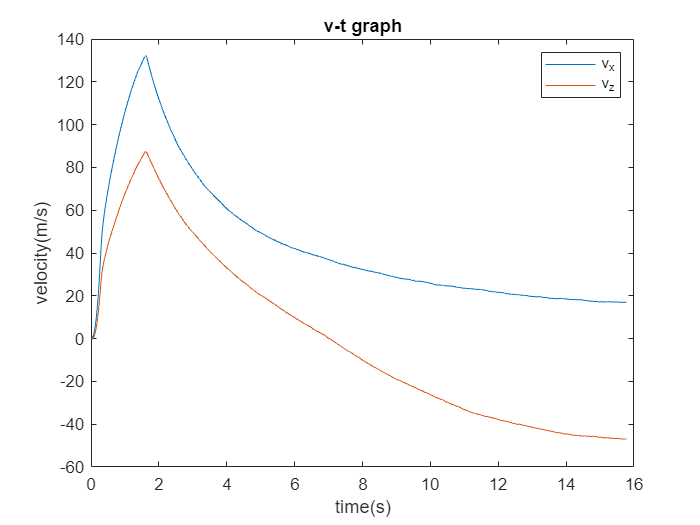

clc; clear; close all; format compact;

CleanedData = struct2array(load('Cleaned Acceleration Data'));

% time  ax  ay  az  omega_x  omega_y  omega_z


t = CleanedData(:,1); %s
a_x_i = CleanedData(:,2); %m/s^2
a_y_i= CleanedData(:,3);
a_z_i = CleanedData(:,4);
omega_x_b = CleanedData(:,5); %rad/s
omega_y_b = CleanedData(:,6); %rad/s
omega_z_b = CleanedData(:,7);

theta_y = cumtrapz(t,omega_y_b); %rad


v_x_i = cumtrapz(t,a_x_i);
v_z_i = cumtrapz(t,a_z_i);

x_i = cumtrapz(t,v_x_i);
z_i = cumtrapz(t,v_z_i);


figure
plot(t,v_x_i,t,v_z_i)
xlabel('time(s)');ylabel('velocity(m/s)');title('v-t graph')
legend('v_x','v_z')

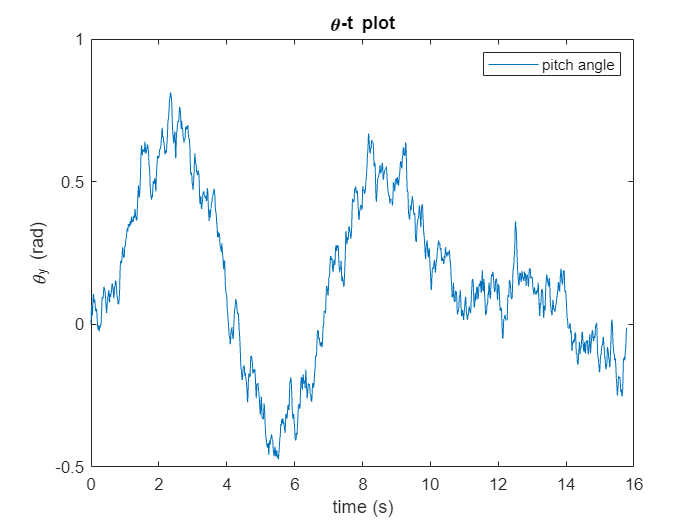

figure
plot(t,theta_y); xlabel('time (s)'); ylabel('\theta_y (rad)'); title('\theta-t plot')
legend('pitch angle')

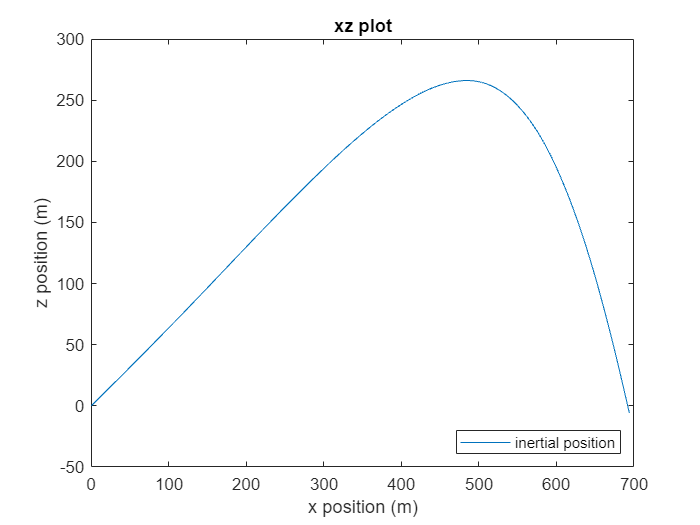

figure
plot(x_i,z_i); xlabel('x position (m)'); ylabel('z position (m)'); title('xz plot') %x is negative for some reason
    legend('inertial position','location','southeast')